# Example 6.25: Experimental Design using GP Models

Note: this script reproduces Example 6.25 (Section 6.6) of **Statistics for Chemical Engineers**: choosing new experiments where the GP prediction is most uncertain. Victor Z UW-Madison, 2024 illustrate uncertainty quantification capabilities of GP

clc; clear all; close all hidden; format bank

rng(0) % For reproducibility
xlb=-1;
xub=+1;

## 3 data points

3 data points

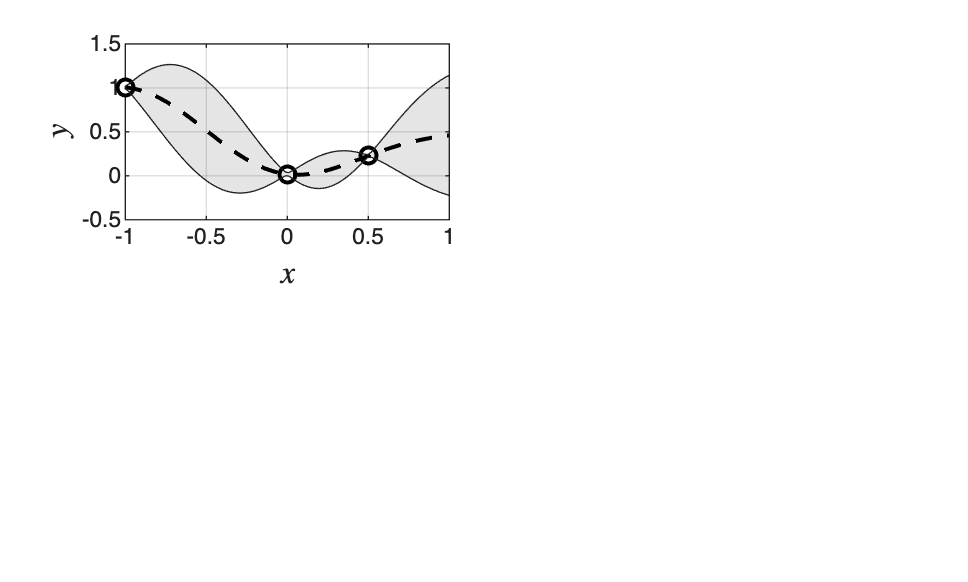

xobs = [-1 0 0.5]';
yobs = xobs.^2 + 0.01*randn(size(xobs));

gprMdl1 = fitrgp(xobs,yobs);

x = linspace(xlb,xub)';
[ypred1,~,yint1] = predict(gprMdl1,x);

figure(1)
subplot(2,2,1)
hold on
scatter(xobs,yobs,'blacko','MarkerFaceColor','w','Linewidth',1.5) % observed data
plot(x,ypred1,'--black','LineWidth',1.5)                                  % mean prediction
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % CIs
axis([xlb xub -0.5 1.5])
grid on
box on
 ylabel('$y$','Interpreter','latex','FontSize',12)
  xlabel('$x$','Interpreter','latex','FontSize',12)

## 4 data points

4 data points

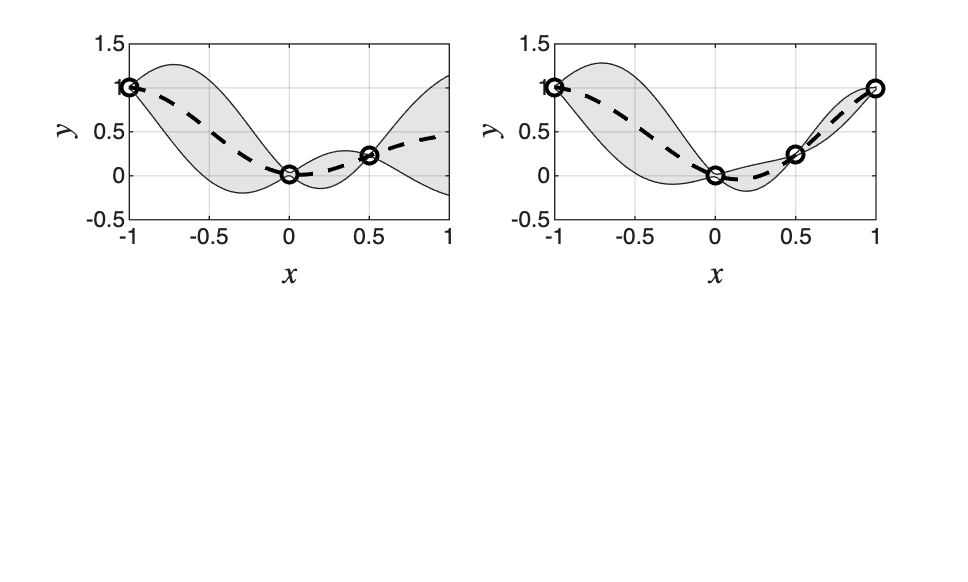

xobs = [-1 0 0.5 1]';
yobs = xobs.^2 + 0.01*randn(size(xobs));

gprMdl1 = fitrgp(xobs,yobs);

x = linspace(xlb,xub)';
[ypred1,~,yint1] = predict(gprMdl1,x);

figure(1)
subplot(2,2,2)
%fplot(@(x) x.^2,[xlb,xub],'-black','LineWidth',1.5)                     % true model
hold on
scatter(xobs,yobs,'blacko','MarkerFaceColor','w','Linewidth',1.5) % observed data
plot(x,ypred1,'--black','LineWidth',1.5)                                  % mean prediction
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % CIs
axis([xlb xub -0.5 1.5])
grid on
box on
 ylabel('$y$','Interpreter','latex','FontSize',12)
  xlabel('$x$','Interpreter','latex','FontSize',12)

## 5 data points

5 data points

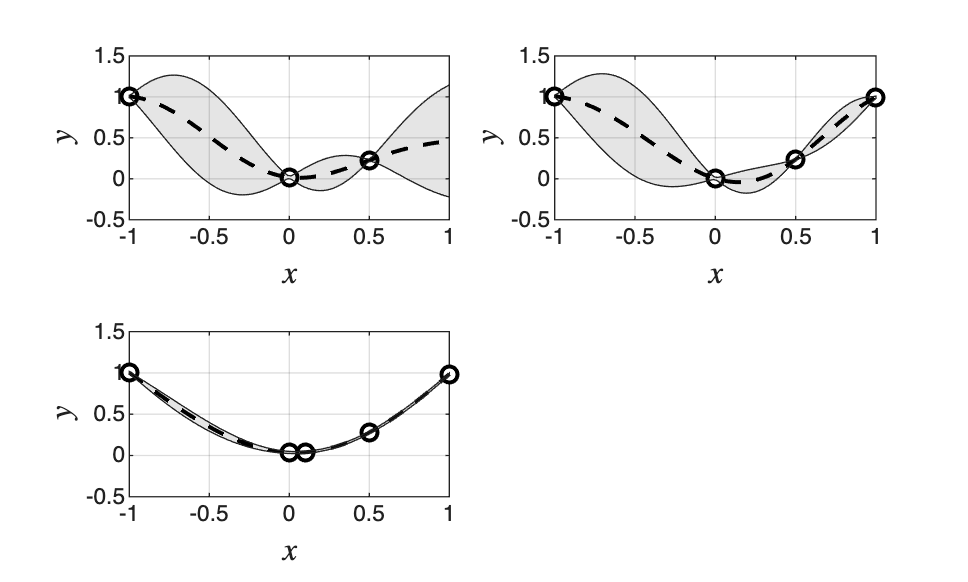

xobs = [-1 0 0.5 1 0.1]';
yobs = xobs.^2 + 0.01*randn(size(xobs));

gprMdl1 = fitrgp(xobs,yobs);

x = linspace(xlb,xub)';
[ypred1,~,yint1] = predict(gprMdl1,x);

figure(1)
subplot(2,2,3)
%fplot(@(x) x.^2,[xlb,xub],'-black','LineWidth',1.5)                     % true model
hold on
scatter(xobs,yobs,'blacko','MarkerFaceColor','w','Linewidth',1.5) % observed data
plot(x,ypred1,'--black','LineWidth',1.5)                                  % mean prediction
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % CIs
axis([xlb xub -0.5 1.5])
grid on
box on
 ylabel('$y$','Interpreter','latex','FontSize',12)
  xlabel('$x$','Interpreter','latex','FontSize',12)

## 6 data points

6 data points

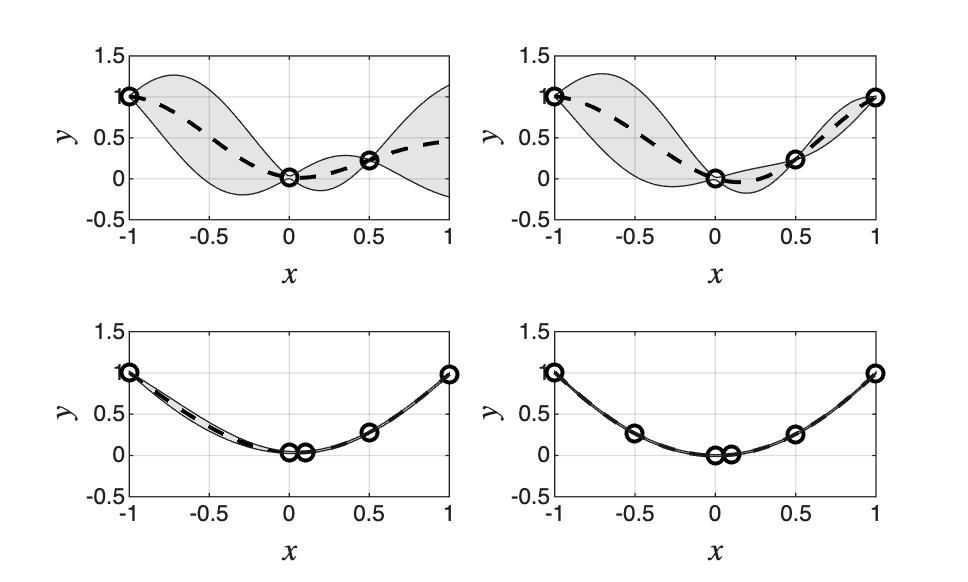

xobs = [-1 0 0.5 1 0.1 -0.5]';
yobs = xobs.^2 + 0.01*randn(size(xobs));

gprMdl1 = fitrgp(xobs,yobs);

x = linspace(xlb,xub)';
[ypred1,~,yint1] = predict(gprMdl1,x);

figure(1)
subplot(2,2,4)
%fplot(@(x) x.^2,[xlb,xub],'-black','LineWidth',1.5)                     % true model
hold on
scatter(xobs,yobs,'blacko','MarkerFaceColor','w','Linewidth',1.5) % observed data
plot(x,ypred1,'--black','LineWidth',1.5)                                  % mean prediction
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % CIs
axis([xlb xub -0.5 1.5])
grid on
box on
 ylabel('$y$','Interpreter','latex','FontSize',12)
  xlabel('$x$','Interpreter','latex','FontSize',12)

print -depsc -r300 ch6_kriging_uq.eps

## Note

As in the book, the GP recommends experiments that reduce prediction uncertainty, balancing exploration and exploitation.